# Sample 9-1

## 離散ウェーブレット変換

ブロック変換のフィルタバンク実装

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Filter bank implementation of block transform

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## 入力信号の生成

(Generation of input)

% Input signal
u = [ 0 3 1 3 1 5 3 0 ]; % Set to even length

### 並列フィルタバンク実装

(Parallel filter bank implementation)

分析フィルタバンクをデシメータで、合成フィルタバンクをインタポレータで実装

% # of channels
nChs = 2;

% Analysis filters
h0 = [ 1  1 ]/2;
h1 = [ 1 -1 ]/2;

% Synthesis filters
f0 = [  1 1 ]; 
f1 = [ -1 1 ];

% Analysis process
s0 = downsample(conv(h0,u),2);
s1 = downsample(conv(h1,u),2);

% Synthesis process
v0 = conv(f0,upsample(s0,2));
v1 = conv(f1,upsample(s1,2));
v = v0 + v1;

## 信号表示

(Signal display)

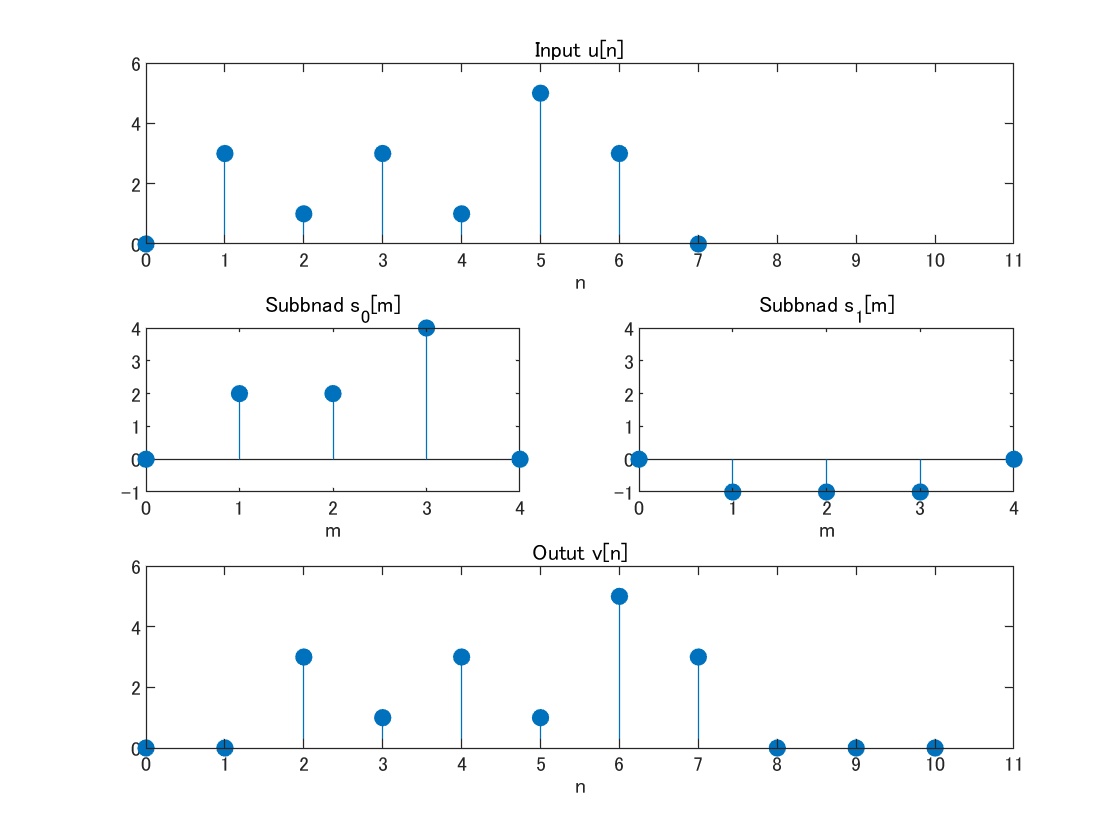

figure(1)
% Input
subplot(3,2,[1,2])
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

% Subband 0
subplot(3,2,3)
stem(0:length(s0)-1,s0,'filled')
title('Subbnad s_0[m]')
xlabel('m')
ax = gca;
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Subband 1
subplot(3,2,4)
stem(0:length(s1)-1,s1,'filled')
title('Subbnad s_1[m]')
xlabel('m')
ax = gca;
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Output
subplot(3,2,[5,6])
stem(0:length(v)-1,v,'filled')
title('Outut v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

### インパルス応答（基底ベクトル）

(Impluse responses of synthesis filters; basis vectors)

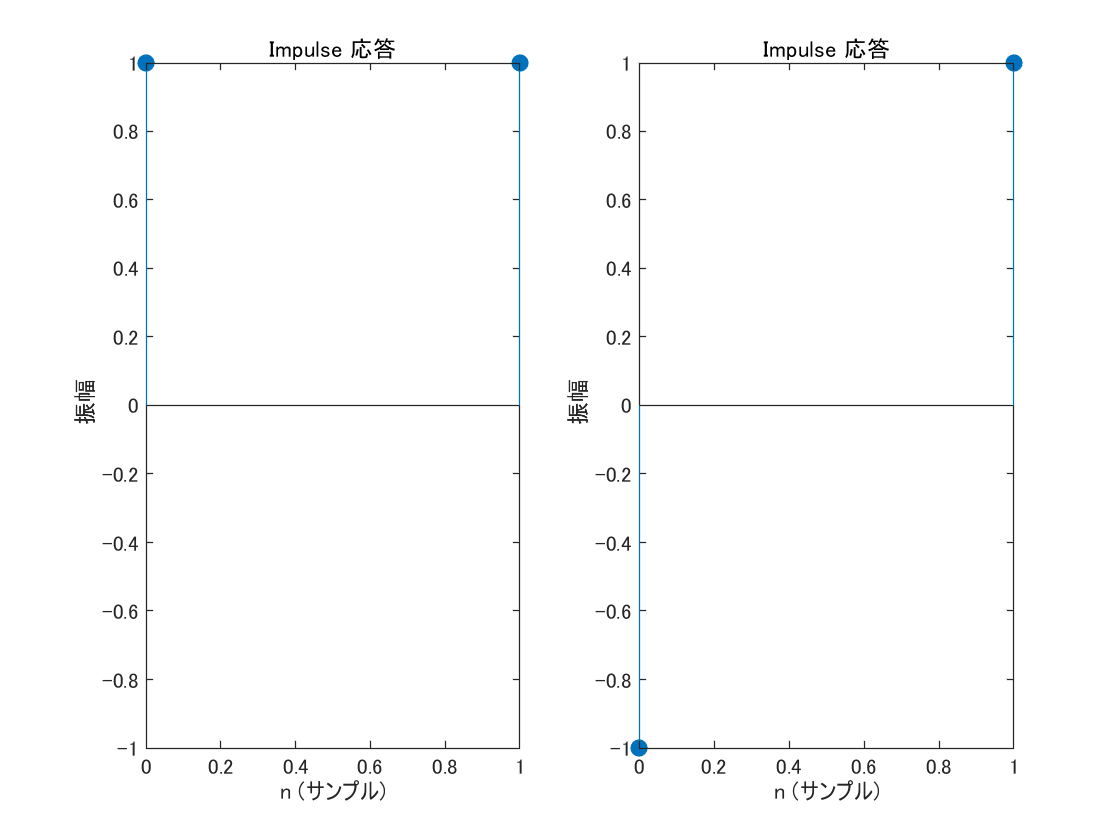

figure(2)
% Low-pass filter
subplot(1,2,1)
impz(f0)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

% High-pass filter
subplot(1,2,2)
impz(f1)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

### 周波数応答

(Frequency responses)

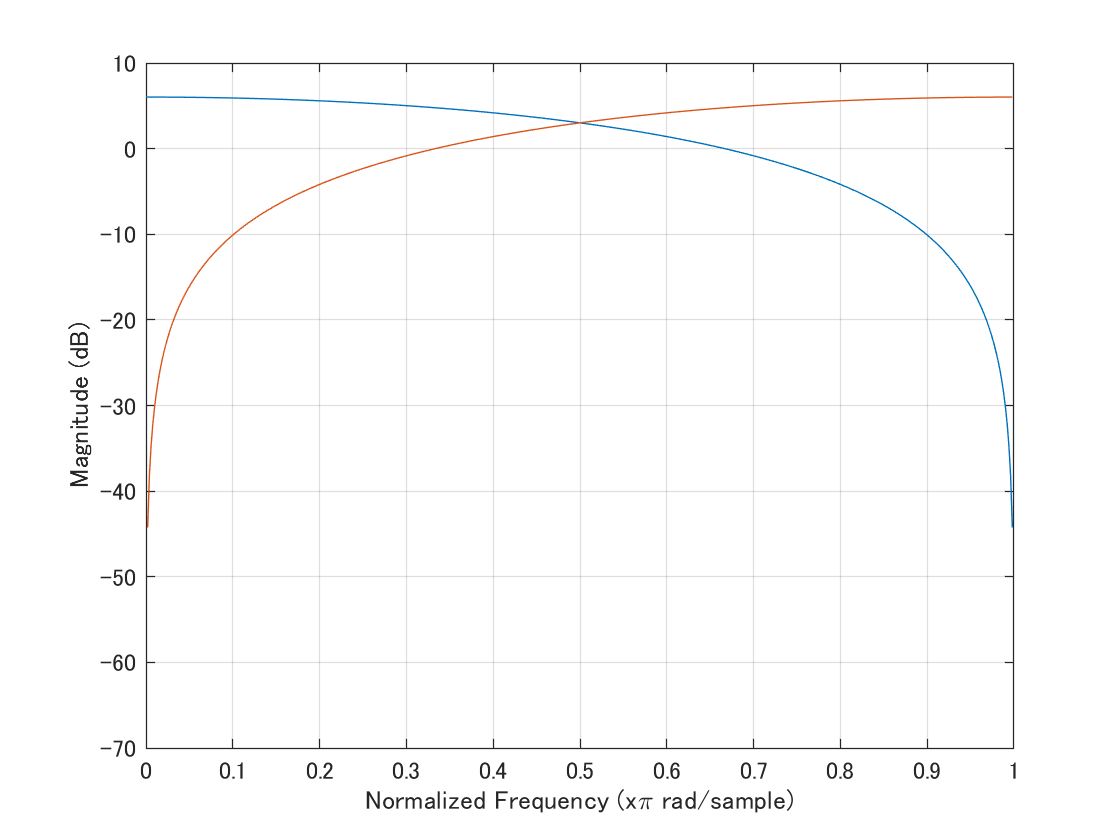

figure(3)
fftPoints = 512;
F = zeros(fftPoints,nChs);
% Low-pass filter
[F(:,1),W] = freqz(f0,1,fftPoints);
% High-pass filter
F(:,2)     = freqz(f1,1,fftPoints);
plot(W/pi,20*log10(abs(F)))
axis([0 1 -70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude (dB)')
grid on

### ポリフェーズ行列実装

(Polyphase matrix implemenation)

フィルタバンクをポリフェースフィルタに分解して、ポリフェーズ行列として実装

% Type-I polyphase filters of analyzer
e00 = h0(1);
e01 = h0(2);
e10 = h1(1);
e11 = h1(2);

% Type-II polyphase filters of synthesizer
r00 = f0(2);
r10 = f0(1);
r01 = f1(2);
r11 = f1(1);


分析合成処理 (Analysis and synthesis process)

% Input Signal
u = [zeros(1,nChs-1) u 0 ];
disp(u)

     0     0     3     1     3     1     5     3     0     0



% Serial/Pallalel conversion
u0 = downsample(u,2,0);
u1 = downsample(u,2,1);
x = [ u0 ; 
      u1 ];
disp(x)

     0     3     3     5     0
     0     1     1     3     0



% Analysis process w/ the polyphase matrix
E = [ e00 e01 ;
      e10 e11 ];
s = E*x;
disp(s)

     0     2     2     4     0
     0     1     1     1     0



% Synthesis process w/ the polyphase matrix
R = [ r00 r01 ;
      r10 r11 ];
y = R*s;
disp(y)

     0     3     3     5     0
     0     1     1     3     0



% Parallel/Serial conversion
v = upsample(y(1,:),2,0) + upsample(y(2,:),2,1);
disp(v)

     0     0     3     1     3     1     5     3     0     0



© Copyright, Shogo MURAMATSU, All rights reserved.